Pasta No: 1

Acuracia_TrainingSet = 95.3757

Acuracia_TestingSet = 95.3488

max = 95.3488

true_cancer = 25

predicted_cancer = 23

true_positive = 23

true_negative = 18

false_cancer = 18

Precision = 100

Recall = 92

specificity = 100

sensibility = 92

F1 = 95.8333

Pasta No: 2

Acuracia_TrainingSet = 94.7977

Acuracia_TestingSet = 90.6977

true_cancer = 25

predicted_cancer = 21

true_positive = 21

true_negative = 18

false_cancer = 18

Precision = 100

Recall = 84

specificity = 100

sensibility = 84

F1 = 91.3043

Pasta No: 3

Acuracia_TrainingSet = 94.7977

Acuracia_TestingSet = 93.0233

true_cancer = 25

predicted_cancer = 22

true_positive = 22

true_negative = 18

false_cancer = 18

Precision = 100

Recall = 88

specificity = 100

sensibility = 88

F1 = 93.6170

Pasta No: 4

Acuracia_TrainingSet = 94.7977

Acuracia_TestingSet = 95.3488

true_cancer = 25

predicted_cancer = 23

true_positive = 23

true_negative = 18

false_cancer = 18

Precision = 100

Recall = 92

specificity = 100

sensibility = 92

F1 = 95.8333

Pasta No: 5

Acuracia_TrainingSet = 94.7977

Acuracia_TestingSet = 93.0233

true_cancer = 25

predicted_cancer = 22

true_positive = 22

true_negative = 18

false_cancer = 18

Precision = 100

Recall = 88

specificity = 100

sensibility = 88

F1 = 93.6170

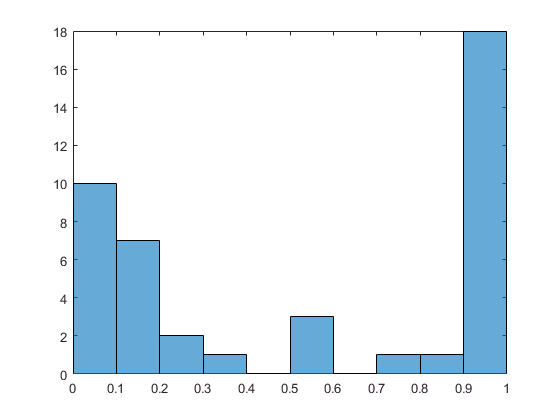

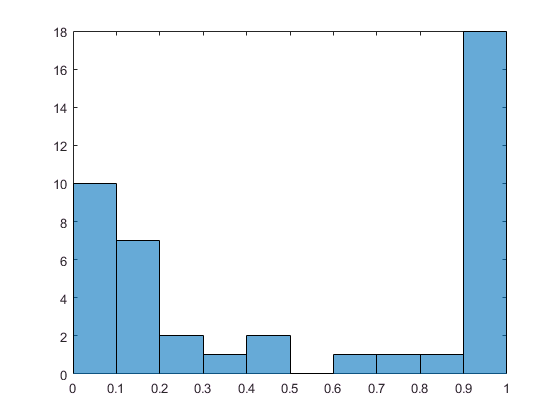

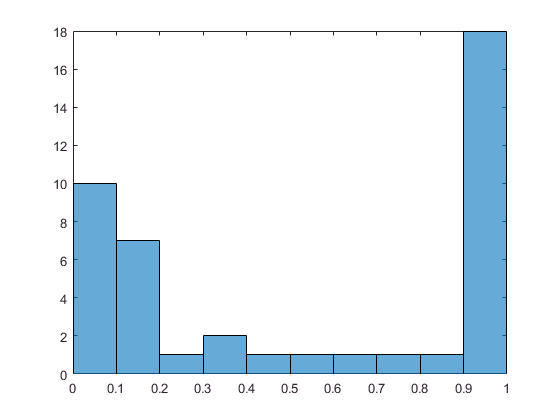

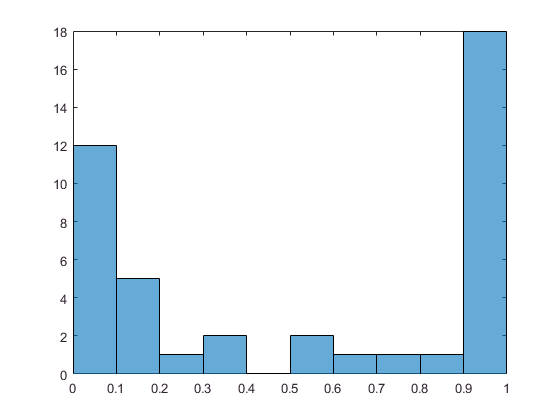

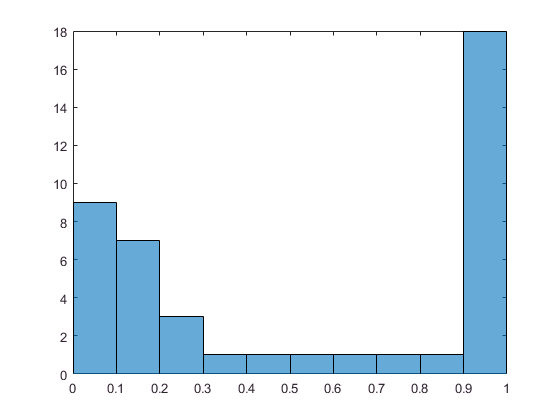

close all;
clear all;

X = xlsread('ovarianInputs.xlsx');
R = xlsread('ovarianTargets.xls');
Y = R(:,1);
m = length(Y);
[r,c] = size(X);
idx = randperm(m);
%y = Y+1;
y = Y;
p = 0.8;
wMax = zeros(101);

xtrain = X(idx(1:round(p*m)),:);
ytrain = y(idx(1:round(p*m)),:); 
xtest  = X(idx(round(p*m)+1:length(idx)),:);
ytest  = y(idx(round(p*m)+1:length(idx)),:);
Num_Pastas= 5;
Acuracia_Media = 0;

for Pasta = 1:Num_Pastas

% Atualiza w pelo gradiente descendente
alpha = 0.001;
w = double(randperm(c+1)/100);
w = -w';  % vetor de pesos iniciais (negativos)
%w =  w'; % vetor de pesos iniciais (positivos)

mtrain  = length(ytrain);
xtrain2 = [ones(mtrain,1) xtrain];
Acuracia_TrainingSet = 0.0;

cont  = 1;
epoch = 1;
while (epoch <= 1200)
     
    if epoch >= 600
        alpha = 0.0001; % aumenta a precisão em 10x após 600 épocas
    end
    
    ztrain  = xtrain2*w;
    htrain = 1.0./(1.0 + exp(-ztrain));
    
    for j = 1:c+1
        somatoria = 0.0;
        for i = 1:mtrain
            somatoria = somatoria + alpha*double((htrain(i) - ytrain(i))*xtrain2(i,j));
        end    
            w(j) = w(j) - somatoria;           
    end    
    
    Loss = 0.0;
    
    for i = 1:mtrain
        Loss = Loss + ytrain(i)*log(htrain(i)) + (1-ytrain(i))*log(1-htrain(i));
    end
    Loss = Loss * (-1.0/mtrain);
    perda(cont) = Loss;
    cont = cont + 1;
            
    ytrainpred = double(htrain > 0.5);
    %ytrainpred = ytrainpred+1;
    Acuracia_TrainingSet = mean(double(ytrainpred == ytrain))*100;
    epoch = epoch + 1;
end

fprintf('Pasta No: %d',Pasta);

%if Pasta == 1 
%    max = Acuracia_TrainingSet
%    PastaMax = Pasta;
%else 
%    if Acuracia_TrainingSet > max
%        max = Acuracia_TrainingSet;
%        wMax = w;
%        PastaMax = Pasta;
%    end
%end

Acuracia_TrainingSet
figure
plot(perda);
histogram(htrain,10); 

mtest  = length(ytest);
xtest2 = [ones(mtest,1) xtest];
ztest  = xtest2*w;

% Evaluate the Model (Test DataSet)
htest = 1.0./(1.0 + exp(-ztest));
ytestpred = double(htest > 0.5);
ytestpred_sem = double(htest <= 0.5);

Acuracia_TestingSet = mean(double(ytestpred == ytest))*100
histogram(htest,10); 

Acuracia_Media = Acuracia_Media + Acuracia_TestingSet;

if Pasta == 1 
    max = Acuracia_TestingSet
    PastaMax = Pasta;
else 
    if Acuracia_TestingSet > max
        max = Acuracia_TestingSet;
        wMax = w;
        PastaMax = Pasta;
    end
end


% Matriz de Confusão
true_cancer      = sum(double(ytest == 1))
true_no_cancer    = sum(double(ytest == 0))
predicted_cancer = sum(double(ytestpred == 1)) 
true_positive    = sum(double(ytest == 1) .* double(ytestpred == 1))
true_negative    = sum(double(ytest == 0) .* double(ytestpred_sem == 1))

false_cancer = sum(double(ytest == 0))

Precision = 100.0*true_positive/predicted_cancer
Recall = 100.0*true_positive/true_cancer

specificity = 100.0*true_negative/true_no_cancer
sensibility = 100.0*true_positive/true_cancer
%F1 Score

F1 = 2*Precision*Recall/(Precision + Recall)

perda = 1;
end


PastaMax

PastaMax = 1

Acuracia_Media = Acuracia_Media/5

Acuracia_Media = 93.4884

max

max = 95.3488

xlswrite('w-cf-5fold.xls',wMax);


